## Getting videos

### Create paths:

videoList = "video_list.txt"

videoList = "video_list.txt"


% CREATING PATHS
% video folder
videoFolderPath = strcat('Z:\Projects\РФФИ-Норвегия\Данные\', ...
    'Экспериментальные данные в лаборатории\', ...
    'Droplet freezing facility data\Generating droplets\VIDEO_DATA');
% cropping folder
croppingFolderPath = strcat(videoFolderPath, '\', "cropping_data");
% data of cropping
dataPath = strcat(croppingFolderPath, '\', "cropping_video.csv");
 
dataCell = splitlines(fileread(strcat(croppingFolderPath,'\',videoList)));
disp(strcat("Count of videos: ", string(length(dataCell))));

Count of videos: 4


### Load videos from list:

Choose analyzing range and click "Load videos"

loadRange =[1 inf];

% checking the end of the analyzingRange
if length(dataCell) < loadRange(2)
    loadRange(2) = length(dataCell);
end
 

uploadCount = loadRange(2) + 1 - loadRange(1);
disp(strcat("Total count of upload videos: ", string(uploadCount)));

Total count of upload videos: 4



allVideoNames = cell(1,loadRange(2));
allObj = cell(1,loadRange(2));
allVideos = cell(1,loadRange(2));

parfor cellNum = loadRange(1):loadRange(2)
    allVideoNames{cellNum} = string(dataCell{cellNum});
    disp(strcat(string(cellNum),") ", allVideoNames{cellNum}));
    allObj{cellNum} = VideoReader(strcat(videoFolderPath,...
        '\', allVideoNames{cellNum}));
    % total frame range
    frameRange = [1 allObj{cellNum}.NumFrames];
    disp(strcat("Loading ", string(frameRange(2)), " frames..."));
    
    allVideos{cellNum} = allObj{cellNum}.read(frameRange);
    disp("...video uploaded.");
    
end

4) 0065_photron_avi.avi
Loading 441 frames...
...video uploaded.
3) 0059_photron_avi.avi
Loading 1067 frames...
...video uploaded.
2) 0043_photron_avi.avi
Loading 1073 frames...
...video uploaded.
1) 0042_photron_avi.avi
Loading 440 frames...
...video uploaded.


#### Analyzing settings

Chose **analyzingRange**, 

**intensity threshold** *(from 1 to 256; what intensity in diffImage is a threshold for droplet appearing)*, 

**scale koeficient** (*for increasing peaks high*),

**frame limit** *(count of frames, exceeding of which without EMD-changing means new droplets), *

**smoothSpan** - span of the moving average (1 ...).

**polyOrder** - order of polinominal fitting.

**baseSide** - side for finding count of crops.

analyzeFlag = false

analyzeFlag = logical
   0


analyzingList ="analyze_list.txt";

threshold =  40

threshold = 40

scaleKoef = [4 0.0]

scaleKoef =      4     0


frameLimit = 75

frameLimit = 75

smoothSpan = 5

smoothSpan = 5

% SET order of polinominal fit
upPolyOrder = 1

upPolyOrder = 1

downPolyOrder = 1

downPolyOrder = 1

polyOrder = [upPolyOrder downPolyOrder];
% SET Threshold quantile value of detrending signal [up down]
quantileThreshold  = [1.0 0.80]

quantileThreshold =     1.0000    0.8000


baseSide = "down"

baseSide = "down"

% SET BASE SIDE (1 - up; 2 - down)
switch baseSide
    case "up"
        baseFrameSide = 1;
    case "down"
        baseFrameSide = 2;
    otherwise 
        baseFrameSide = 2;
end

% changing EMD-levels
upScaleKoef = scaleKoef(1); 
downScaleKoef = scaleKoef(2);

% SET Quantile value (0...1)
maxEMDQuantileValue = [0.90 0.90];
maxSecDifQuantileValue = [0.5 0.5];

% SET Max distance (in UpDownKoef*frameLimit between peaks)
UpDownKoef = 3;

% create analyzing cells
if analyzeFlag
    analyzeCell = splitlines(fileread(strcat(croppingFolderPath,'\',analyzingList)));
else
    analyzeCell = cellfun(@char,allVideoNames,'UniformOutput',false)';
end

disp(strcat("Count of videos: ", string(length(analyzeCell))));

Count of videos: 4


#### VIDEO ANALYZING:

Before clicking "ANALYZE", click "APPLY SETTINGS"

1) ANALYZING: 0042_photron_avi.avi


Count of detected crops: 2


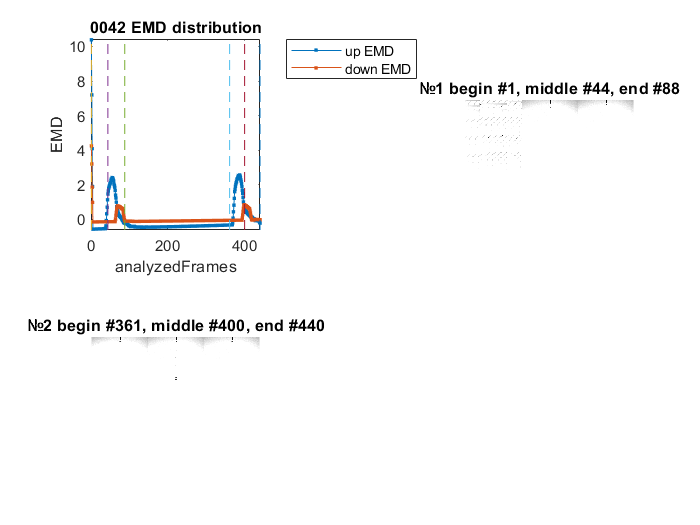

Figure & template were saved


Last row:


    test      video_ranges   
    ____    _________________

     42     {'37-88,361-440'}



Saved row:


    {[42]}    {'1-88,361-440'}



2) ANALYZING: 0043_photron_avi.avi


Count of detected crops: 4


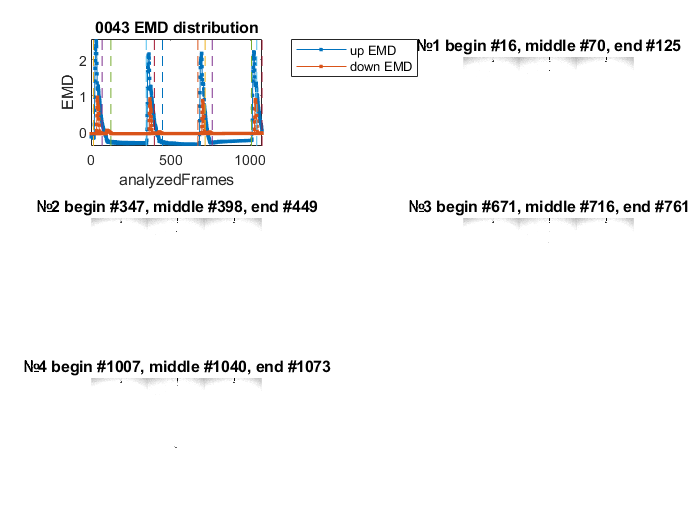

Figure & template were saved


Last row:


    test                video_ranges            
    ____    ____________________________________

     43     {'17-125,344-446,675-759,1007-1073'}



Saved row:


    {[43]}    {'16-125,347-449,…'}



3) ANALYZING: 0059_photron_avi.avi


Count of detected crops: 4


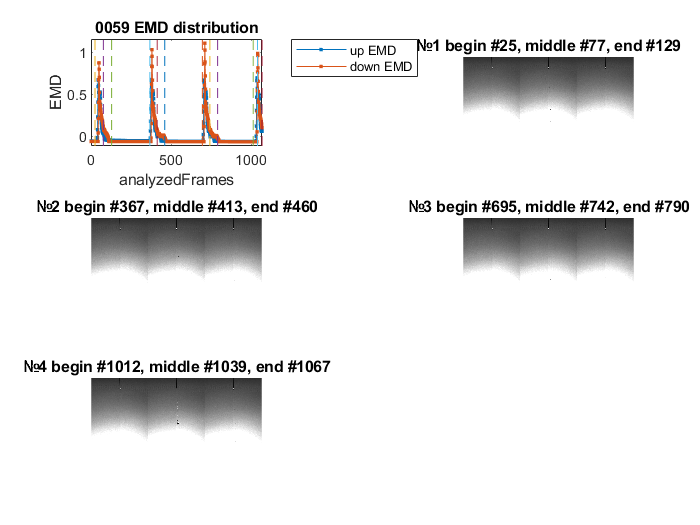

Figure & template were saved


Last row:


    test                video_ranges            
    ____    ____________________________________

     59     {'34-113,367-460,695-790,1018-1067'}



Saved row:


    {[59]}    {'25-129,367-460,…'}



4) ANALYZING: 0065_photron_avi.avi


Count of detected crops: 2


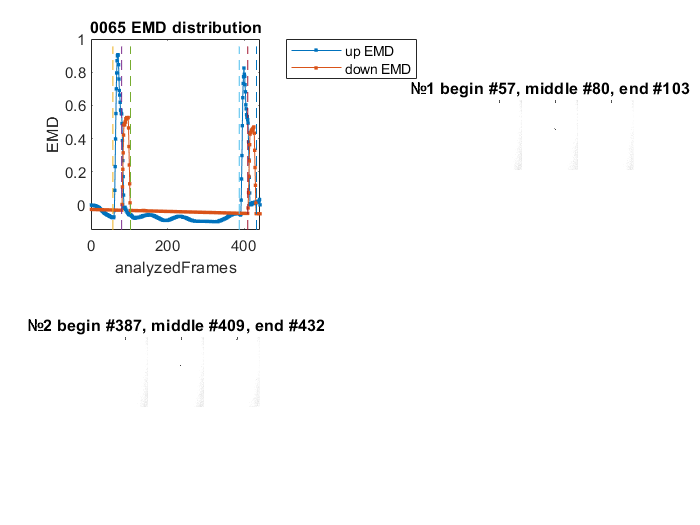

Figure & template were saved


Last row:


    test       video_ranges   
    ____    __________________

     65     {'57-103,388-432'}



Saved row:


    {[65]}    {'57-103,387-432'}




 

%ANALYZE VIDEOS
for cellNum = loadRange(1):loadRange(2) %!!!! parfor cellNum = loadRange(1):loadRange(2)
    currentVideoName = allVideoNames{cellNum};
    if ~isempty(find(contains(analyzeCell, currentVideoName), 1))
        disp(strcat(string(cellNum),") ANALYZING: ", currentVideoName));
     
        obj = allObj{cellNum};
        video = allVideos{cellNum};
        frameRange = [1 allObj{cellNum}.NumFrames];
        
        % current test number
        text = split(currentVideoName,'_');
        testNum = uint16(str2double(text(1)));
    
        % ANALYZE!
        [selectedFrames, analyzedFrames, EMD,...
    templateImg] = cropVideoEMD(obj, video, frameRange, threshold,...
    upScaleKoef, downScaleKoef, frameLimit, smoothSpan, polyOrder,...
    baseFrameSide, maxEMDQuantileValue, maxSecDifQuantileValue,...
    UpDownKoef, quantileThreshold);

        % DISPLAY EMD-Values and images
        figure;
        dispFrames(selectedFrames, analyzedFrames, EMD, video, ...
            testNum);
        % SAVE EMD-Values and images as fig.
        figPath = strcat(croppingFolderPath, '\',sprintf('%04u',testNum), ...
            "_EMD",".fig");
        savefig(figPath);
        %close(gcf);
        templPath = strcat(croppingFolderPath, '\',sprintf('%04u',testNum),...
        "_template",".jpg");
        imwrite(templateImg,templPath)
        disp("Figure & template were saved");
        
        % SAVING CROP-RANGE
        
        % Create ranges of crop in string format
        cropRanges = cropRanges2str(selectedFrames);
        
        % READ TABLE
        T = readtable(dataPath);
        
        % delete previos ranges
        toDelete = T.test == testNum;
        lastrow = T(toDelete,:);
        T(toDelete,:) = [];
        % add new value
        savedRow = {testNum,cropRanges};
        T = [T;savedRow];
        
        % WRITE TABLE
        writetable(T,dataPath);
        disp('Last row:');
        disp(lastrow);
        disp('Saved row:');
        disp(savedRow);
    end
end